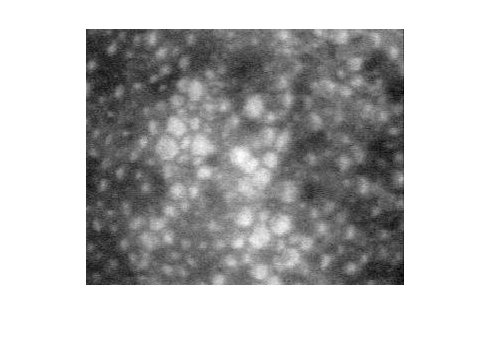

orig = imread('cornea.tif');
figure, imshow(orig);

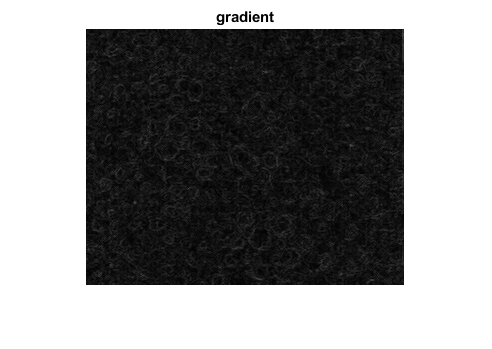

ee = strel('disk',1); 
% calculem el gradient. Ho podem fer morfològic
grad=imsubtract(imdilate(orig,ee),imerode(orig,ee));
figure,imshow(grad),title('gradient')

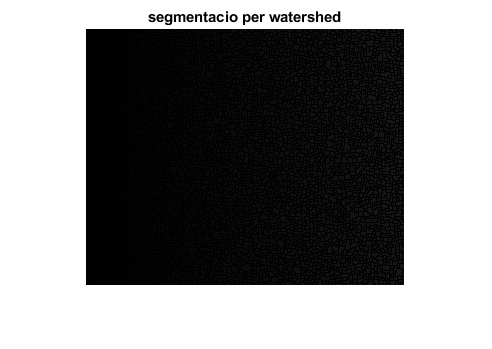

% mirem de segmentar les cèlules fent watershed sobre la imatge gradient
segm=watershed(grad);
figure,imshow(segm), title('segmentacio per watershed')

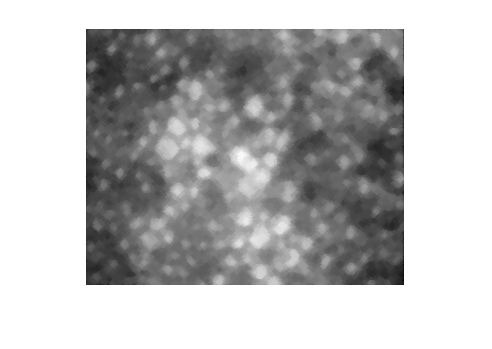

% resultat sobresegmentat. Cal treballar amb markers
%% marker-controlled watershed
% usarem els màxims regionals com a markers de les cèlules
% la imatge és molt sorollosa. Cal filtrar abans
ee=strel('disk',2);
filt=imopen(imclose(orig,ee),ee); %filtre OC
figure,imshow(filt)

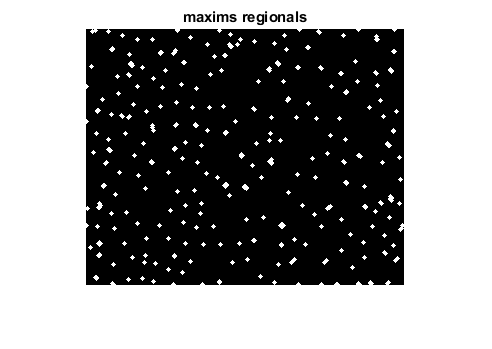

rm=imregionalmax(filt);
figure,imshow(rm),title('maxims regionals')

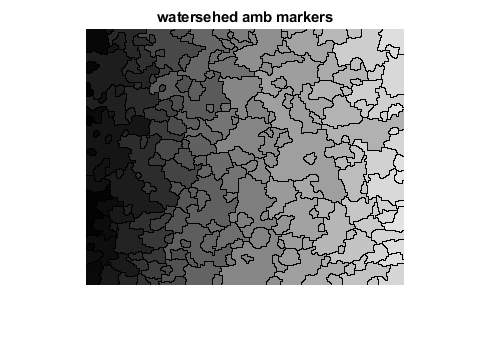

% Usem els maxims regionals com a markers pel watershed
segm=watershed(imimposemin(grad,rm));
figure,imshow(segm),title('watersehed amb markers')

Feu un overlay, en color, dels contorns obtinguts sobre la imatge original. Us sembla correcta la segmentació? O ens em oblidat alguna cosa ?

imshow(filt)
hold on

[M,N] = size(filt)

M = 256

N = 318

color = zeros(M,N);
color(:,:,1) = ones(M,N)*255;
imshow(color)

Error using images.internal.imageDisplayValidateParams>validateCData (line 115)
Multi-plane image inputs must be RGB images of size MxNx3.

Error in images.internal.imageDisplayValidateParams (lin

alpha 